# W4

## 1.

[x, fs] = audioread("week3_sample_dist.wav");
freq = 2*pi*6000/fs;
f_dip = 0.9;


$$K = \frac{z^2 - 2zcos(freq) + 1}{z^2 - 2azcos(freq) + a^2}  = \frac{1}{a^2}$$


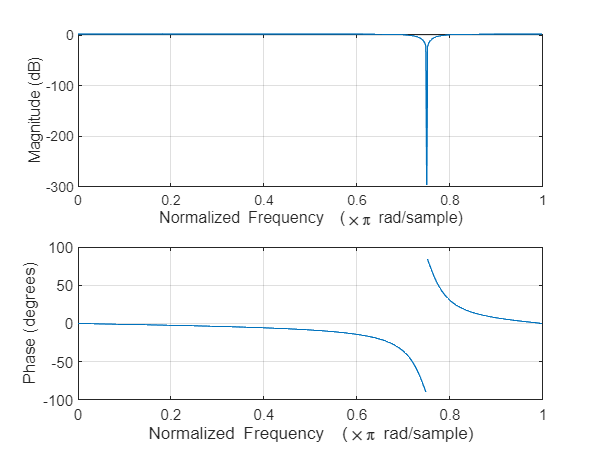

K = 1/(f_dip^2);
Y = K*[1 -2*cos(freq) 1];
X = [1 -2*f_dip*cos(freq) f_dip^2]; 
freqz(Y, X)

figure

## 2.

Given the same filter

The difference function can be derived as follows


$$\frac{Y}{X} = \frac{1 - 2cos(\omega_{n})z^{-1} + z^{-2}}{1 - 2cos(\omega_{n})z^{-1}a + a^2z^{-2}}$$



$${Y}({1 - 2cos(\omega_{n})z^{-1}a + a^2z^{-2}})= {X}({1 - 2cos(\omega_{n})z^{-1} + z^{-2}})$$



$$y_n = 2cos(\omega_{n})y_{n-1}a - y_{n-2}a^2 + x_n - 2cos(\omega_{n})x_{n-1} + x_{n-2}$$


## 3. and 4.

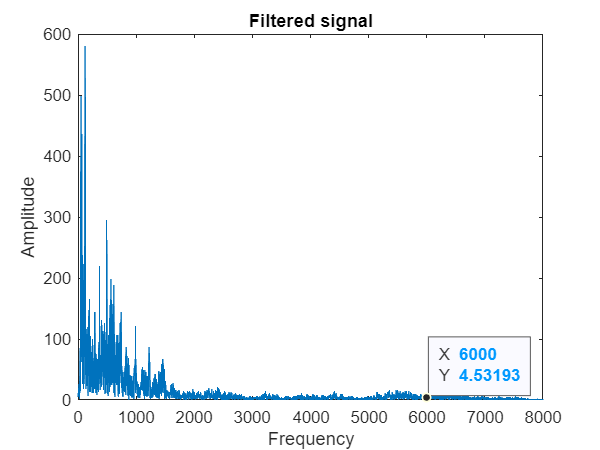

clear
[x, fs] = audioread("week3_sample_dist.wav");
y = zeros(1, length(x));
freq = 2*pi*6000/fs;
f_dip = 0.9;
K = 1/(f_dip^2);
Y = K*[1 -2*cos(freq) 1];
X = [1 -2*f_dip*cos(freq) f_dip^2]; 
for k = 3:length(x)
    y(k) = 2.*cos(freq).*y(k - 1).*f_dip - y(k - 2).*f_dip.^2 + x(k) - 2.*cos(freq).*x(k - 1) + x(k - 2);
end
yf = abs(fft(y, fs));
plot(linspace(1, length(yf), length(yf)), yf)
title("Filtered signal")
xlabel("Frequency")
ylabel("Amplitude")
xlim([0 8000])
ax = gca;
chart = ax.Children(1);
datatip(chart,6000, 1);

%sound(y)

## 5.


$$A_{dB} = 20log(\frac{4,53}{4398,58}) \approx -59,745 dB$$


## 6.

:D